# **BS1 USRP N310 Transmitter **

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 2.5e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "3/4";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame 20 for setup1
dataParams.numFrames      = 10000;   % Number of frames to transmit
dataParams.enableScopes   = false;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Switch to enable or disable the data diagnostic output

## Initialize Transmitter Parameters

radioDevice            = "N310";  % Choose the radio device for transmission
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
centerFrequency        = 2.503e9;
gain                   = 50;  % Set radio gain
gain                   = 50

gain = 50

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);

Checking radio connections...



% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);

## Generate Transmitter Waveform 

### **Transmit Frame Structure**

**Synchronization Symbol (SS)**

**Reference Symbol (RS)**

**Header Symbol**

**Pilot Signals**

**DC and Guard Subcarriers**

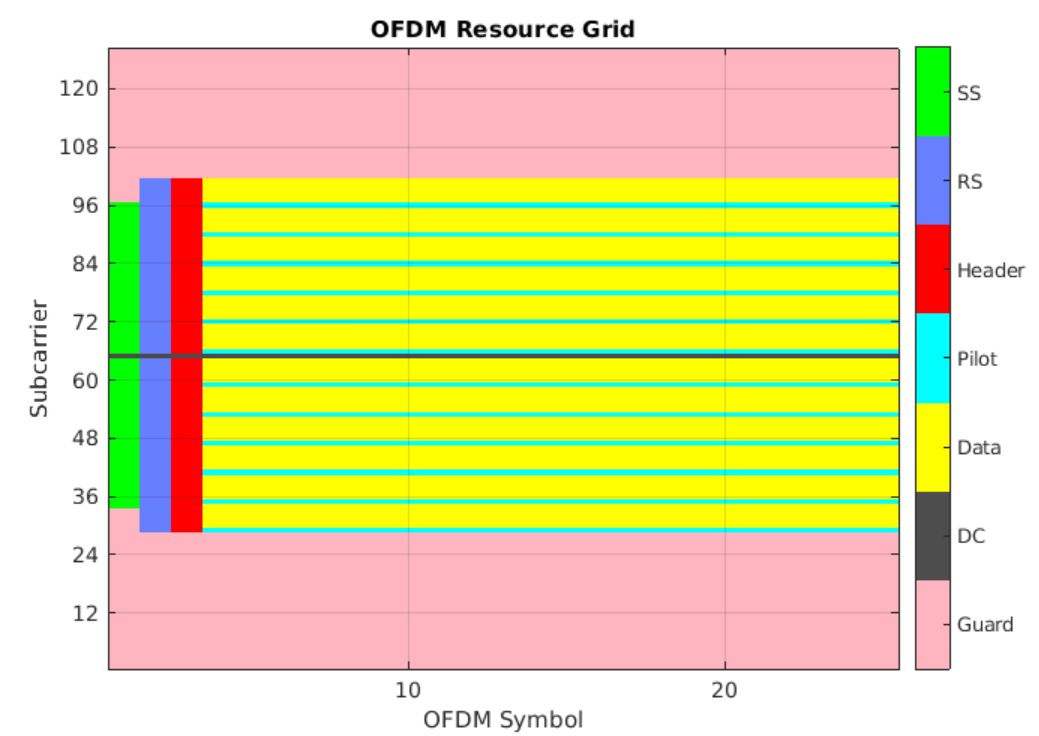

### Transmitter processing

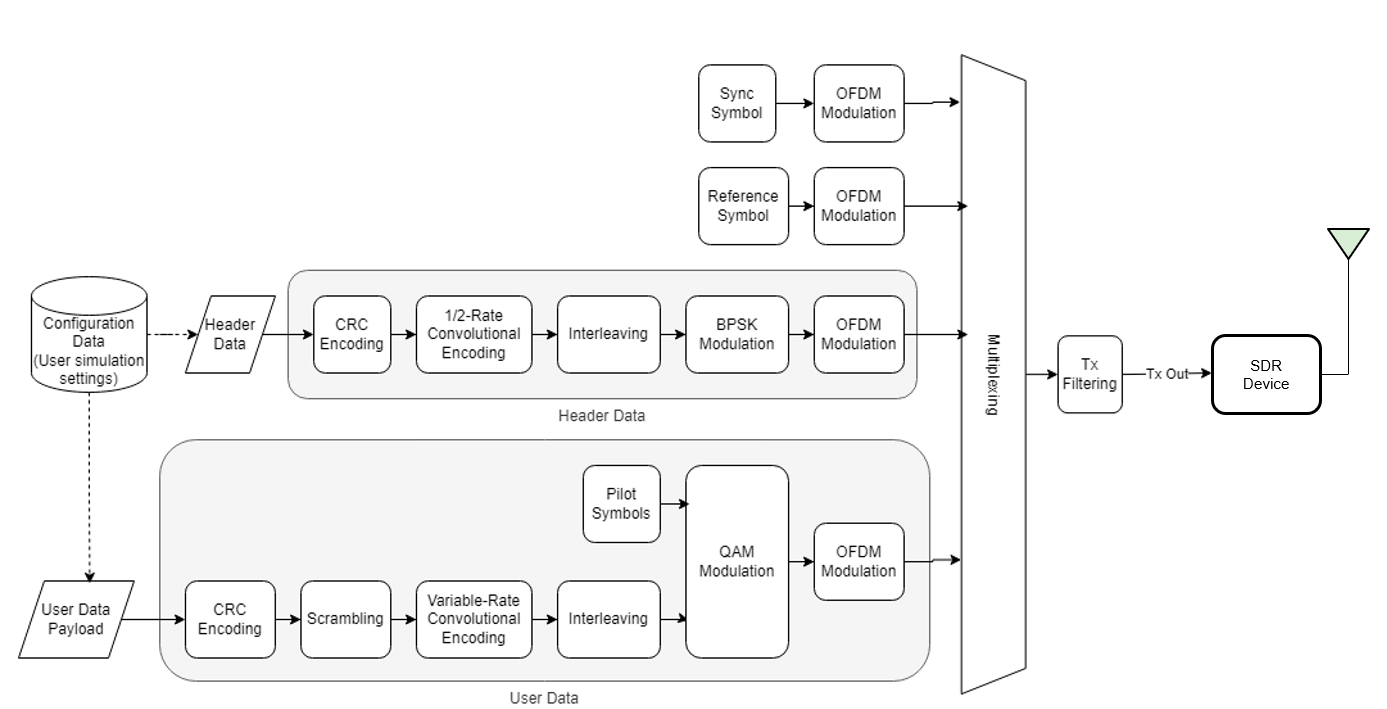

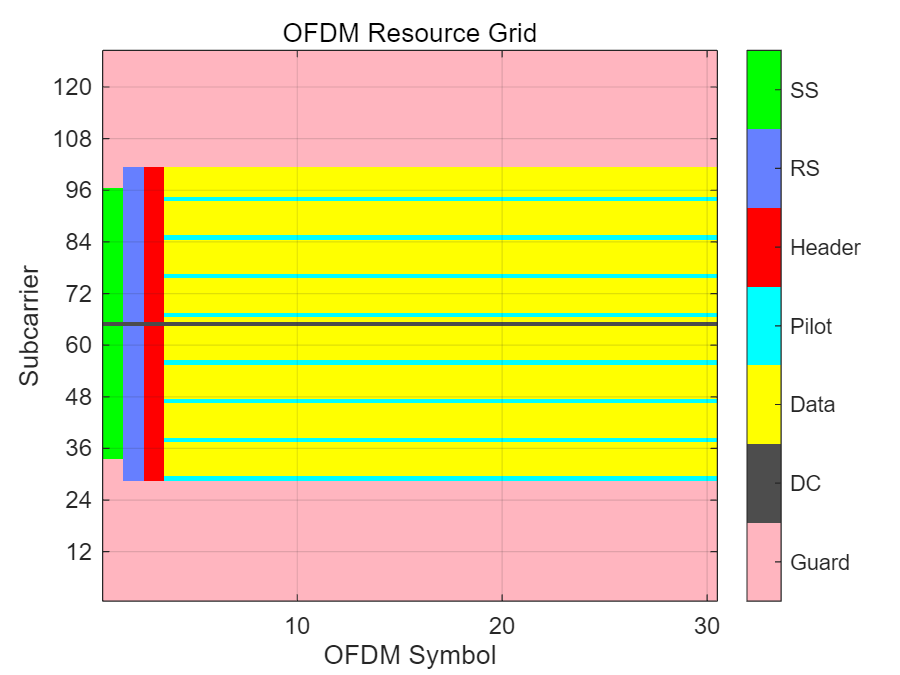


% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);
tunderrun = 0; % Initialize count for underruns

% A known payload is generated in the function helperOFDMSetParams with
% respect to the calculated trBlkSize
% Store data bits for BER calculations
txParam.txDataBits = trBlk;
[txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

% Display the grid if verbosity flag is enabled
if dataParams.verbosity
    helperOFDMPlotResourceGrid(txGrid,sysParam);
end


% Repeat the data in a buffer for PLUTO radio to make sure there are less
% underruns. The receiver decodes only one frame from where the first
% synchroization signal is received
txOutSize = length(txOut);
if contains(radioDevice,'PLUTO') && txOutSize < 48000
    frameCnt = ceil(48000/txOutSize);
    txWaveform = zeros(txOutSize*frameCnt,1);
    for i = 1:frameCnt
        txWaveform(txOutSize*(i-1)+1:i*txOutSize) = txOut;
    end
else
    txWaveform = txOut;
end

if dataParams.enableScopes
    spectrumAnalyze(txOut);
end
transmit_flag = 0;
txWaveform = [txWaveform];
% txWaveform = [txWaveform,txWaveform];
% txWaveform = [txWaveform,txWaveform,txWaveform,txWaveform];


## Transmit Over Radio

for frameNum = 1:sysParam.numFrames+1
    underrun = radio(txWaveform);
    tunderrun = tunderrun + underrun;  % Total underruns
    if transmit_flag == 0
        fprintf('-----------BS1 N310 starting transmitting at Rfq %s!----------------\n', mat2str(centerFrequency))
        fprintf('-----------TR antennal %s----------------\n', mat2str(channelmapping))
        fprintf('-----------Gain %s----------------', mat2str(gain))
        transmit_flag = 1;
    end
end

-----------BS1 N310 starting transmitting at Rfq 2503000000!----------------


-----------TR antennal 1----------------


-----------Gain 50----------------

if transmit_flag == 1
    fprintf('----------BS1 N310 ending of transmitting at Rfq %s!-------------', mat2str(centerFrequency))
end

----------BS1 N310 ending of transmitting at Rfq 2503000000!-------------

% radio.CenterFrequency = 3.1e9;
% transmit_flag = 0;
% for frameNum = 1:sysParam.numFrames+1
%     underrun = radio(txWaveform);
%     tunderrun = tunderrun + underrun;  % Total underruns
%     if transmit_flag == 0
%         fprintf('-----------starting transmitting at frequency band 2!----------------')
%         transmit_flag = 1;
%     end
% end
% if transmit_flag == 1
%     fprintf('----------ending of transmitting at frequency band 2-------------')
% end

% Clean up the radio System object
release(radio);